HW3  Plotting and Graphics

## Homework Exercises

1)  Generate a list of the first 100 powers of 2. The following function selects the first digit of a number x: $\lfloor \frac{x}{10^{\lfloor \log_{10}(x)\rfloor}}\rfloor$.  (The half brackets are the floor or greatest integer function).  Plot a histogram of the first digits of 100 powers of 2. Use this to estimate the probability that the first digit of a power of 2 is *1*. What is the probability that the fist digit is *2*? and so on. This phenomena you observe is referred to as *Benford's Law*: For *most* numbers, the probability that the first digit is *d* is given by $\log_{10}\left(1+\frac{1}{d}\right)$. Plot this function (in red) on the same axes as the histogram.  

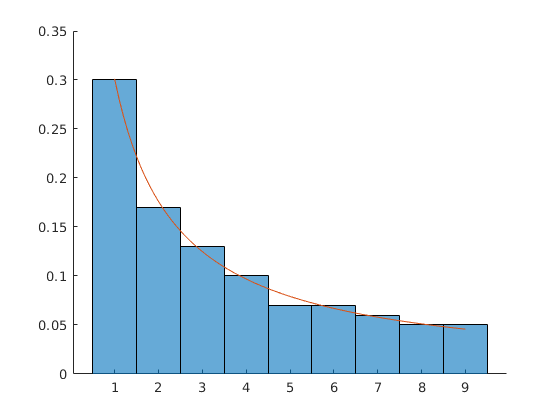

pow2 = 2.^(1:100);
firstdig = floor(pow2 ./ 10.^floor(log10(pow2)));
x = 1:0.1:9;
prob = log10(1 + (1 ./ x));


hold on
histogram(firstdig, 'Normalization',"pdf")
plot(x, prob)
hold off

2) For the following 5  examples, set *x=linspace(a,b,n)* for the given values of *a*, *b*, and *n*. Calculate *y=f(x)* for the given function *f(x)*. Plot with *plot(x,y,s)* for the given formatting string *s*. Explain the result of the formatting string.

a) f(x) = sin(x), a=0, b=4 *pi, n=24, s='rs-'.

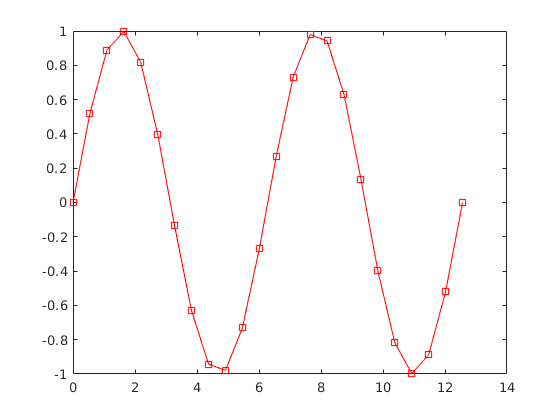

x = linspace(0, 4*pi, 24);
y = sin(x);
plot(x, y, 'rs-' )

% 'r' makes it red
% 's' plots points with squares
% '-' connects points with lines

b) f(x) = arccos(x), a=-1, b=1, n=24, s='mo'.

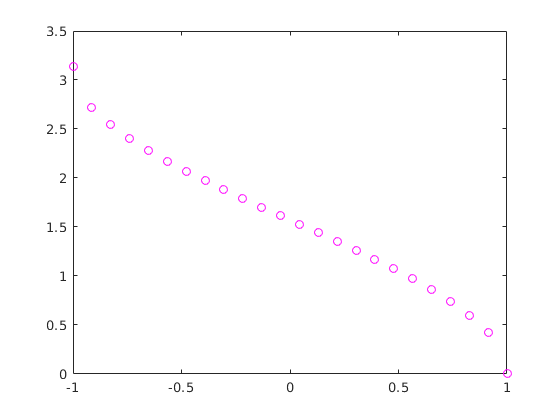

x = linspace(-1, 1, 24);
y = acos(x);
plot(x, y, 'mo')

% 'm' makes it magenta
% 'o' plots the points with circles

c) f(x) = 2^x, a=-2, b=4, n=12, s='gd:'.

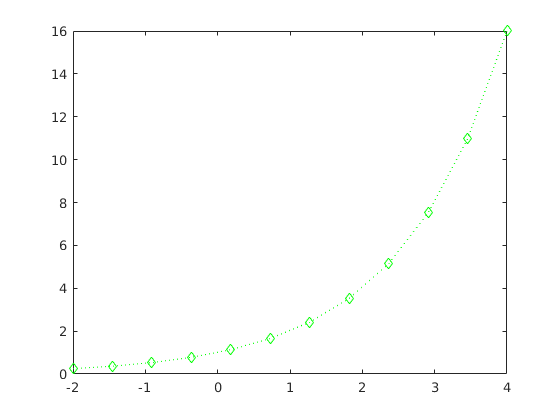

x = linspace(-2, 4, 12);
y = 2.^x;
plot(x, y, 'gd:')

% 'g' makes the color green
% 'd' plots points with diamonds
% ':' connects points with dotted lines

d)  f(x) = log10(x), a=0.1, b=10, n=20, s='c--'.

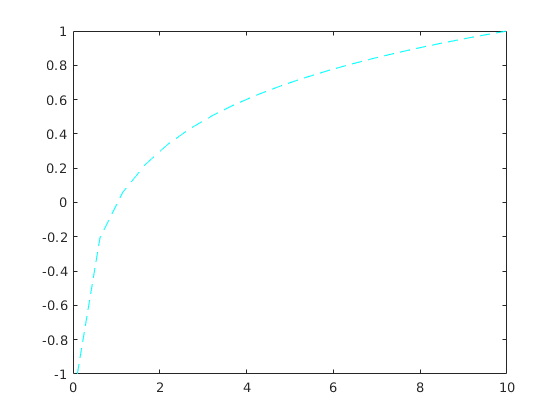

x = linspace(0.1, 10, 20);
y = log10(x);
plot(x, y, 'c--')

% 'c' makes the color cyan
% '--' connects points with dashed lines

e) f(x) = x^2, a=-5, b=5, n=20, s='b*-.'.

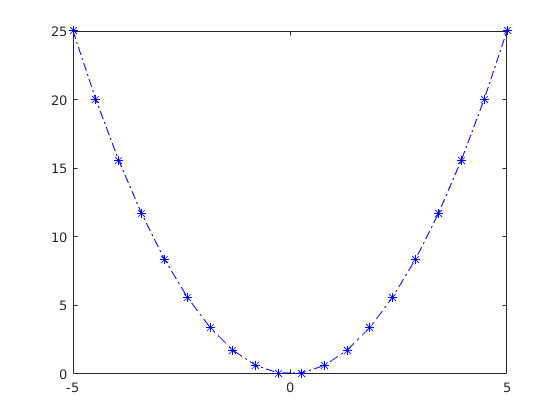

x = linspace(-5, 5 , 20);
y = x .^ 2;
plot(x, y, 'b*-.')

% 'b' selects color blue
% '*' plots points with asterisk 
% '-.' connects points with a dot-dashed lined

3) Graph the given function on a domain that shows all the important features of the function (intercepts, extrema, etc.)  on the domain specified. Use enough points so that your plot appears smooth. Label the horizontal and vertical axis with Matlab's *xlabel()* and *ylabel()* commands. Include a *title()*.

a) $y=x^2-2x-3$


x = -5:0.1:5

x =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


y = (x.^2) - (2*x) - 3

y =    32.0000   30.8100   29.6400   28.4900   27.3600   26.2500   25.1600   24.0900   23.0400   22.0100   21.0000   20.0100   19.0400   18.0900   17.1600   16.2500   15.3600   14.4900   13.6400   12.8100   12.0000   11.2100   10.4400    9.6900    8.9600    8.2500    7.5600    6.8900    6.2400    5.6100    5.0000    4.4100    3.8400    3.2900    2.7600    2.2500    1.7600    1.2900    0.8400    0.4100         0   -0.3900   -0.7600   -1.1100   -1.4400   -1.7500   -2.0400   -2.3100   -2.5600   -2.7900


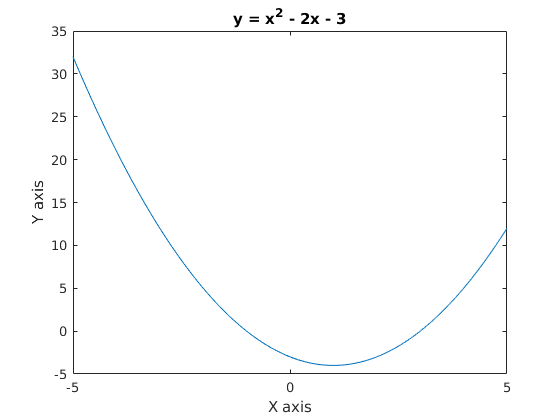

plot(x, y)
xlabel('X axis')
ylabel('Y axis')
title('y = x^2 - 2x - 3')

b) $y=x^3-3x^2-28x+60$

x = -7:0.1:9

x =    -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000   -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000


y = (x.^3) - (3 * x .^ 2) - (28 * x) + 60

y =  -234.0000 -218.1390 -202.7520 -187.8330 -173.3760 -159.3750 -145.8240 -132.7170 -120.0480 -107.8110  -96.0000  -84.6090  -73.6320  -63.0630  -52.8960  -43.1250  -33.7440  -24.7470  -16.1280   -7.8810         0    7.5210   14.6880   21.5070   27.9840   34.1250   39.9360   45.4230   50.5920   55.4490   60.0000   64.2510   68.2080   71.8770   75.2640   78.3750   81.2160   83.7930   86.1120   88.1790   90.0000   91.5810   92.9280   94.0470   94.9440   95.6250   96.0960   96.3630   96.4320   96.3090


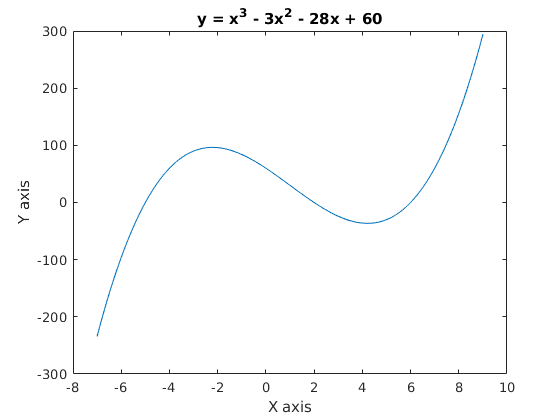

plot(x,y)
xlabel('X axis')
ylabel('Y axis')
title('y = x^3 - 3x^2 - 28x + 60')

c) $y=x e^{-x^2}$ on $[-5,5]$

x = -5:0.1:5

x =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


y = x .* exp(-(x .^ 2))

y =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0004   -0.0006   -0.0011   -0.0018   -0.0030   -0.0048   -0.0076   -0.0116   -0.0174   -0.0255   -0.0366   -0.0514   -0.0705   -0.0945   -0.1237   -0.1581   -0.1972   -0.2399   -0.2843   -0.3280   -0.3679   -0.4004   -0.4218   -0.4288   -0.4186   -0.3894   -0.3409   -0.2742   -0.1922   -0.0990


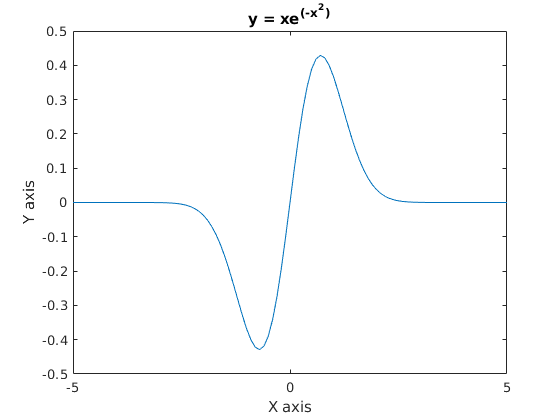

plot(x, y)
xlabel('X axis')
ylabel('Y axis')
title('y = xe^{(-x^2)}')
hold off

4) Take the torus plot from the worksheet. Add to it (in cyan) the plot of a parametric curve which winds 20 times around in the phi variable while making one rotation in the theta variable.

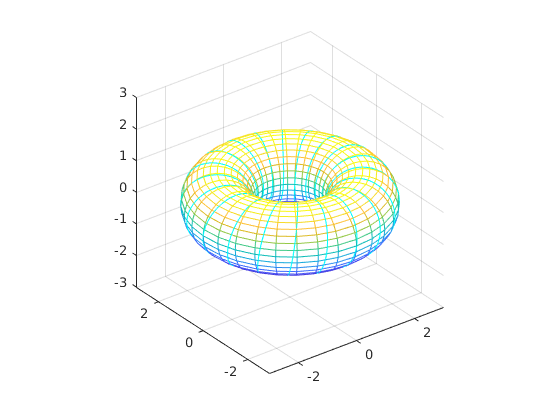

% torus: copied from PlottingGraphics.mlx worksheet
theta=0:pi/16:2*pi;
psi=0:pi/16:2*pi;
[T,P]=meshgrid(theta,psi);
a=2;b=1;
X=(a+b*cos(P)).*cos(T);
Y=(a + b*cos(P)).*sin(T);
Z=b*sin(P);
syms t
mesh(X,Y,Z)
hold on
fplot3(cos(t)*(a + b*cos(2*pi + 20*t)), ...
       sin(t)*(a + b*cos(2*pi + 20*t)), ...
       b*sin(2*pi + 20*t), ...
       [0, 2*pi], 'c')
axis([-3,3,-3,3,-3,3])
axis('square')
hold off

5) One of the most important tools of applied linear algebra is the singular value decomposition. Given a kxn matrix A, the singular value decomposition of A is a factorization of A = U S V', where U is a kxk orthogonal matrix, V is an nxn orthogonal matrix, and S is kxn and  diagonal (only non-zero entries are on the main diagonal where row index i =column index j). If A is not square then the 'main diagonal of S'  ends at the (k,k) entry if k<n and at the (n,n) entry if k>n. The diagonal entries of S are non-negative and are called the singular values of A. The columns of V' are ordered so that  the singular values  in S decrease in  magnitude along the  diagonal. In MATLAB, the singular value decomposition is obtained by the function *svd.* If called in the form *[U,S,V]=svd(A)* then all pieces are returned. 

One use of the singular value decomposition is in image analysis -- finding less complex images which well approximate the given image. 

Load the image graycat from the worksheet. 

load('graycat.mat')

The image elements are 8 bit integers. To apply the svd we want to make them floating point numbers.

floatcat=rescale(graycat)

floatcat =     0.9922    0.9922    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961
    0.9961    0.9961    0.9961    1.0000    1.0000    1.0000    1.0000    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.99

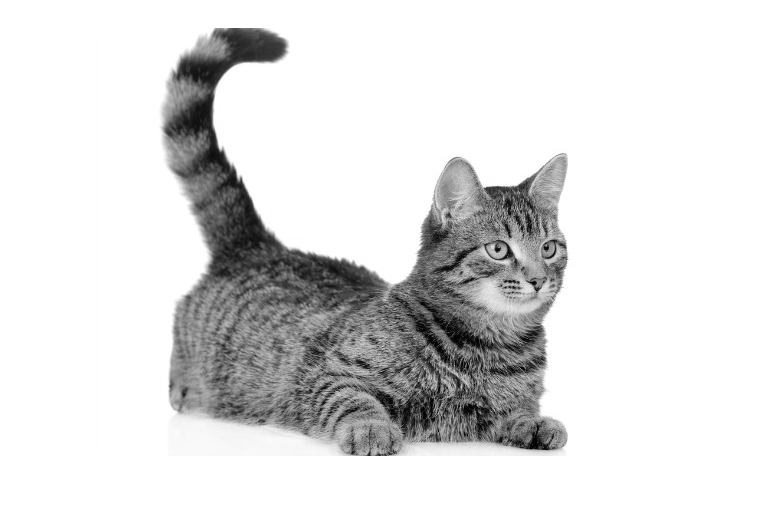

imshow(floatcat)% imshow can handle images with floating point entries

a) Generate the U,S,V of the svd decomposition of floatcat.

[U,S,V] = svd(floatcat);

b) Extract  the diagonal in S and check that the singular values decrease fairly quickly.  What is the largest singular value?  What is the 10th largest?

format short
dg = diag(S) % decreases fairly fast

dg =   409.4179
   70.7796
   46.3977
   35.0351
   26.3292
   21.0605
   17.3472
   16.2197
   13.7045
   11.1286


dg(1) % largest value

ans = 409.4179

dg(10) % 10th largest

ans = 11.1286

c) Suppose that s10 is the 10th largest singular value. An approximation to A is given by U*S10*V' where 

S10 represents the result of setting all singular values below the 10th largest to zero. (Use the < logical selection criterion from an earlier assignment and array multiplication to generate S10.)  Display the images resulting from using the 10 largest singular values, the 20 largest singular values, and the 100 largest singular values. 

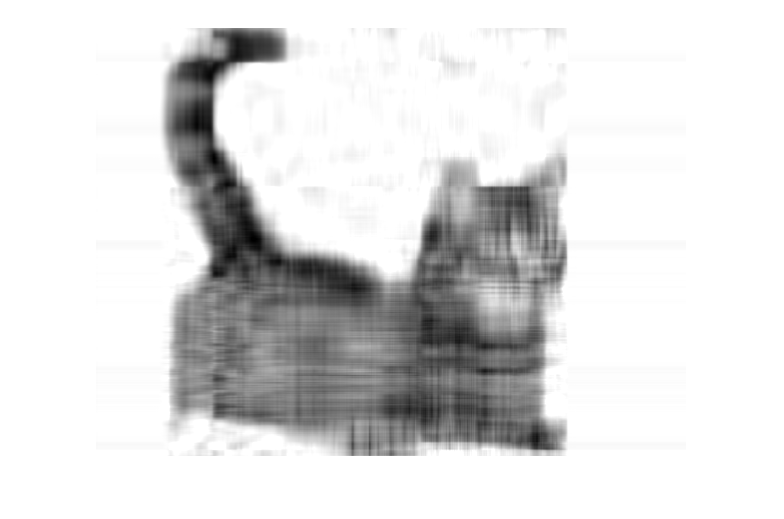

S10 = S .* (S >= dg(10)); % 10 largest
S20 = S .* (S >= dg(20)); % 20 largest
S100 = S .* (S >= dg(100)); % 100 largest
imshow(U*S10*V')

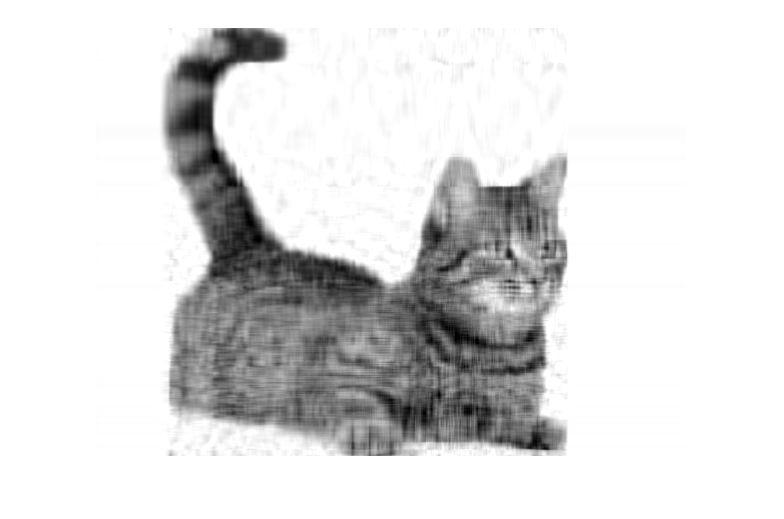

imshow(U * S20 * V')

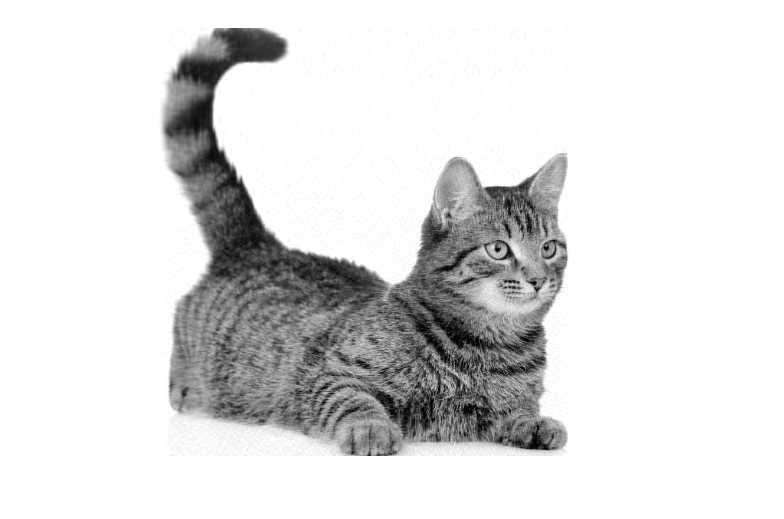

imshow(U * S100 * V')